# Dimension generator for patch antenna

## Antenna properties

%% Adjust the required frequency and dielectric constant
fv = 6.2e9; % in GHz
er = 2.55;

## Set the bounds for the antenna

% Length (in mm)
lmin = 10;
lmax = 25;

% Height (in mm)
hmin = 0.01;
hmax = 1;

% Width (in mm)
wmin = 1;
wmax = 25;

% Total points to run the algorithm
RefPoints = 100;

## Generator

% Bounds (L, W, H)
L =  [lmin wmin hmin 0];
U =  [lmax wmax hmax 0.9999];

N = 3;
Functions = {@(x)f1(x, fv, er), @f2};
M = length(Functions);

f1_vals = zeros(1, RefPoints);
f2_vals = zeros(1, RefPoints);

rng(42);
X = {};

i = 1;
while i <= RefPoints
    z = [1e-6 0.01]; % Initial decision vector
    w = [10 0.4]; % adjust priority
    w = w / norm(w); % Normalize `w'
    
    assert (length(z) == M);
    assert (length(w) == M);
    
    % Non-Linear Conditions for ASF
    C1 = @(x) ASFCondition(x(1:N), Functions{1}, z(1), w(1));
    C2 = @(x) ASFCondition(x(1:N), Functions{2}, z(2), w(2));
    
    % Final Objective function
    Objective = @(x) ASF(x, Functions, M, z, w);
    
    % Make a proper guess which satisfies the constraints
    fprintf("[%2d] Getting feasible solution ...\n", i);
    x0 = rand(1, N+1) .* U;
    while C1(x0) > 0 || C2(x0) > 0
         x0 = rand(1, N+1) .* U;
    end
    
    fprintf("[%2d] Solving ...\n", i);
    options = optimoptions('fmincon', ...
        'Algorithm', 'sqp', ...
        'TolFun', 1e-9, ...
        'TolX', 1e-9, ...
        'MaxFunctionEvaluations', 1e5, ...
        'Display', 'none');
    [x, fval, exitflag, output] = fmincon(Objective, x0, [], [], [], [], ...
        L, U, ...
        @(x)Constraint(x, C1, C2), options);
    
    % Don't add the solution if it converges to an infeasible point
    if exitflag < 0
        continue;
    end
    
    X{i} = x;
    f1_vals(i) = Functions{1}(x);
    f2_vals(i) = Functions{2}(x);
    i = i+1;
end

[ 1] Getting feasible solution ...


[ 1] Solving ...


[ 2] Getting feasible solution ...


[ 2] Solving ...


[ 3] Getting feasible solution ...


[ 3] Solving ...


[ 4] Getting feasible solution ...


[ 4] Solving ...


[ 5] Getting feasible solution ...


[ 5] Solving ...


[ 6] Getting feasible solution ...


[ 6] Solving ...


[ 7] Getting feasible solution ...


[ 7] Solving ...


[ 8] Getting feasible solution ...


[ 8] Solving ...


[ 9] Getting feasible solution ...


[ 9] Solving ...


[10] Getting feasible solution ...


[10] Solving ...


[11] Getting feasible solution ...


[11] Solving ...


[12] Getting feasible solution ...


[12] Solving ...


[13] Getting feasible solution ...


[13] Solving ...


[14] Getting feasible solution ...


[14] Solving ...


[15] Getting feasible solution ...


[15] Solving ...


[16] Getting feasible solution ...


[16] Solving ...


[17] Getting feasible solution ...


[17] Solving ...


[18] Getting feasible solution ...


[18] Solving ...


[19] Getting feasible solution ...


[19] Solving ...


[20] Getting feasible solution ...


[20] Solving ...


[21] Getting feasible solution ...


[21] Solving ...


[22] Getting feasible solution ...


[22] Solving ...


[23] Getting feasible solution ...


[23] Solving ...


[24] Getting feasible solution ...


[24] Solving ...


[25] Getting feasible solution ...


[25] Solving ...


[26] Getting feasible solution ...


[26] Solving ...


[27] Getting feasible solution ...


[27] Solving ...


[28] Getting feasible solution ...


[28] Solving ...


[29] Getting feasible solution ...


[29] Solving ...


[30] Getting feasible solution ...


[30] Solving ...


[31] Getting feasible solution ...


[31] Solving ...


[32] Getting feasible solution ...


[32] Solving ...


[33] Getting feasible solution ...


[33] Solving ...


[34] Getting feasible solution ...


[34] Solving ...


[35] Getting feasible solution ...


[35] Solving ...


[36] Getting feasible solution ...


[36] Solving ...


[37] Getting feasible solution ...


[37] Solving ...


[38] Getting feasible solution ...


[38] Solving ...


[39] Getting feasible solution ...


[39] Solving ...


[40] Getting feasible solution ...


[40] Solving ...


[41] Getting feasible solution ...


[41] Solving ...


[42] Getting feasible solution ...


[42] Solving ...


[43] Getting feasible solution ...


[43] Solving ...


[44] Getting feasible solution ...


[44] Solving ...


[45] Getting feasible solution ...


[45] Solving ...


[46] Getting feasible solution ...


[46] Solving ...


[47] Getting feasible solution ...


[47] Solving ...


[48] Getting feasible solution ...


[48] Solving ...


[49] Getting feasible solution ...


[49] Solving ...


[50] Getting feasible solution ...


[50] Solving ...


[51] Getting feasible solution ...


[51] Solving ...


[52] Getting feasible solution ...


[52] Solving ...


[53] Getting feasible solution ...


[53] Solving ...


[54] Getting feasible solution ...


[54] Solving ...


[55] Getting feasible solution ...


[55] Solving ...


[56] Getting feasible solution ...


[56] Solving ...


[57] Getting feasible solution ...


[57] Solving ...


[58] Getting feasible solution ...


[58] Solving ...


[59] Getting feasible solution ...


[59] Solving ...


[60] Getting feasible solution ...


[60] Solving ...


[61] Getting feasible solution ...


[61] Solving ...


[62] Getting feasible solution ...


[62] Solving ...


[63] Getting feasible solution ...


[63] Solving ...


[64] Getting feasible solution ...


[64] Solving ...


[65] Getting feasible solution ...


[65] Solving ...


[66] Getting feasible solution ...


[66] Solving ...


[67] Getting feasible solution ...


[67] Solving ...


[68] Getting feasible solution ...


[68] Solving ...


[69] Getting feasible solution ...


[69] Solving ...


[70] Getting feasible solution ...


[70] Solving ...


[71] Getting feasible solution ...


[71] Solving ...


[72] Getting feasible solution ...


[72] Solving ...


[73] Getting feasible solution ...


[73] Solving ...


[74] Getting feasible solution ...


[74] Solving ...


[75] Getting feasible solution ...


[75] Solving ...


[76] Getting feasible solution ...


[76] Solving ...


[77] Getting feasible solution ...


[77] Solving ...


[78] Getting feasible solution ...


[78] Solving ...


[79] Getting feasible solution ...


[79] Solving ...


[80] Getting feasible solution ...


[80] Solving ...


[81] Getting feasible solution ...


[81] Solving ...


[82] Getting feasible solution ...


[82] Solving ...


[83] Getting feasible solution ...


[83] Solving ...


[84] Getting feasible solution ...


[84] Solving ...


[85] Getting feasible solution ...


[85] Solving ...


[86] Getting feasible solution ...


[86] Solving ...


[87] Getting feasible solution ...


[87] Solving ...


[88] Getting feasible solution ...


[88] Solving ...


[89] Getting feasible solution ...


[89] Solving ...


[90] Getting feasible solution ...


[90] Solving ...


[91] Getting feasible solution ...


[91] Solving ...


[92] Getting feasible solution ...


[92] Solving ...


[93] Getting feasible solution ...


[93] Solving ...


[94] Getting feasible solution ...


[94] Solving ...


[95] Getting feasible solution ...


[95] Solving ...


[96] Getting feasible solution ...


[96] Solving ...


[97] Getting feasible solution ...


[97] Solving ...


[98] Getting feasible solution ...


[98] Solving ...


[99] Getting feasible solution ...


[99] Solving ...


[100] Getting feasible solution ...


[100] Solving ...


## Results

fprintf("Optimal results:\n")

Optimal results:


[x, idx]= min(f1_vals);
fprintf("Dimensions:");

Dimensions:

disp(X{idx}(1:3));

   15.1521   17.1640    0.0100


fprintf("Error:");

Error:

disp(f1_vals(idx));

   1.3725e-08


## Plots

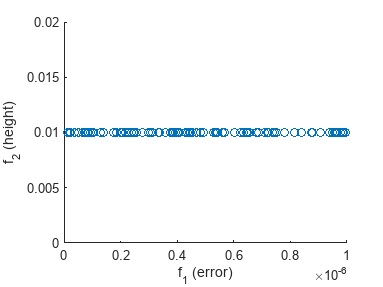

scatter(f1_vals, f2_vals);
xlabel("f_1 (error)");
ylabel("f_2 (height)");
ylim([0 0.02]);
xlim([0 1e-6]);

## Functions

function ret = f1(x, fv, er)
    l = x(1) * 1e-3;
    W = x(2) * 1e-3;
    h = x(3) * 1e-3;
    
    ep_w = (er+1)/2 + (er-1)/(2 * sqrt(1 + 10*h/W));
    delta_w = 0.412 * h * ((ep_w+0.3)*(W/h+0.264))/((ep_w-0.258)*(W/h+0.813));
    fr = 3e8 ./ (2 * (l + delta_w) * sqrt(ep_w));
    ret = abs(fv-fr) * 1e-9;
end

function ret = f2(x)
    ret = x(3);
end
    
function ret = ASFCondition(x, Fn, z, w)
    ret = (Fn(x) - z) ./ w - x(end);
end

function [c, ceq] = Constraint(x, C1, C2)
    c = [C1(x); C2(x)];
    ceq = [];
end

function ret = ASF(x, Functions, M, z, w)
    C = zeros([1 M]);

    x = x(1:end-1);
    for i = 1:M
        C(i) = (Functions{i}(x) - z(i)) ./ w(i);
    end
    ret = max(C);
end
